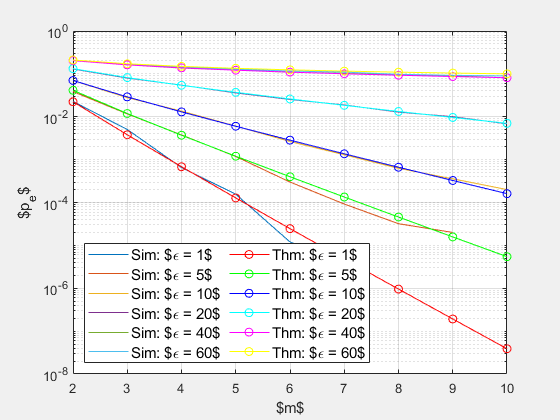

clc
clear 
colorList = ["r","g","b","c","m","y","k"];

addpath('result')
nameList = dir('result/*.mat');
lambdaList = 2:10;
radiusMap = 50; % Map Size
epsilonList = [1, 5, 10, 20, 40, 60];

figure('Visible','on'),
simResult = zeros(length(lambdaList), length(nameList));
for j = 1:length(nameList)
    load(nameList(j).name)
    for i = 1:length(lambdaList)
        p = pe(i,:);
        obs = obsNum(i,:);
        simResult(i,j) = mean(p);
    end
end

semilogy(lambdaList, simResult);
grid on, hold on
xlabel('$m$')
ylabel('$p_e$')
legend('Sim: $\epsilon = 1$', 'Sim: $\epsilon = 5$', 'Sim: $\epsilon = 10$',...
    'Sim: $\epsilon = 20$', 'Sim: $\epsilon = 40$', 'Sim: $\epsilon = 60$', 'Location', 'best')

pe_a = @(lam, epsilon, dv) besseli(0, 2*lam .* sqrt((8*dv^3*epsilon - 6*dv^2*epsilon.^2 + epsilon.^4)/(3*dv^4))) .* exp(- 2*lam);

for i = 1:length(epsilonList)
    p_lam = pe_a(lambdaList, epsilonList(i), radiusMap);
    h = semilogy(lambdaList, p_lam, 'Marker','o');
    h.Color = colorList(i);
end

legend({'Sim: $\epsilon = 1$', 'Sim: $\epsilon = 5$', 'Sim: $\epsilon = 10$',...
    'Sim: $\epsilon = 20$', 'Sim: $\epsilon = 40$', 'Sim: $\epsilon = 60$',...
    'Thm: $\epsilon = 1$', 'Thm: $\epsilon = 5$', 'Thm: $\epsilon = 10$',...
    'Thm: $\epsilon = 20$', 'Thm: $\epsilon = 40$', 'Thm: $\epsilon = 60$'},...
    'NumColumnsMode', 'manual', 'NumColumns', 2, 'Location', 'southwest', 'FontSize', 11)